# フィット概要

・説明変数3つ  (拡散係数**D、**濃度**C**、観察体積の横方向サイズ（＝beam waist)** w0**)

→目的変数 **G(ξ, τ)**を得る 

## ①データの準備

・dataframeの作成　説明変数X (ksai, tau) 1024*2 , 目的変数(cor) 1024*1)

dataframe = table((KSAI)', (TAU)', (COR)')

dataframe = 256×3 table
     Var1       Var2           Var3     
    ______    ________    ______________

    -2.816    0.000763    [1×256 double]
    -2.794    0.000763    [1×256 double]
    -2.772    0.000763    [1×256 double]
     -2.75    0.000763    [1×256 double]
    -2.728    0.000763    [1×256 double]
    -2.706    0.000763    [1×256 double]
    -2.684    0.000763    [1×256 double]
    -2.662    0.000763    [1×256 double]
     -2.64    0.000763    [1×256 double]
    -2.618    0.000763    [1×256 double]
    -2.596    0.000763    [1×256 double]
    -2.574    0.000763    [1×256 double]
    -2.552    0.000763    [1×256 double]
     -2.53    0.000763    [1×256 double]
    -2.508    0.000763    [1×256 double]
    -2.486    0.000763    [1×256 double]



SIZE = size(COR,1)*size(COR,2);
X = zeros(SIZE, 2);
y = zeros(SIZE, 1);
X(:,2) = repmat((TAU)',size(COR,1),1)

X =          0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630
         0    0.7630


A = [];
for i = 1:size(COR,1)
    A = [A;repmat(KSAI(i),size(COR,1),1)];
end
X(:,1) = A;

count = 1;
for k = 1:size(COR,1)
    for t = 1:size(COR,2)
       y(count) = COR(t,k);
       count = count + 1;
    end
end

### 未完成A) parameter 2つ=[tauD, Amplitude] (SP, woを事前代入)

### 完成済B ) parameter 3つ=[wo, tauD, Amplitude]  (SPを事前代入)

numbers_of_parameter = 3;

### 未完成A)  3次元拡散モデル式(parameter 2つ) 　doi: 10.1016/S0076-6879(10)72005-X　式(15.11)**改**

beta0 = [diffusionCoefficient , concentration, w0]

b(1):diffusion_time [s]   

b(2):定数（Amplitudeの立ち上がりの部分)

SP [無単位] =  wz/wx　←**FCSのcalibrationで得る**

x(:,1) = ksai, x(:,2) = tau 

if numbers_of_parameter == 2
kind_of_fitting = "2paras"
volume_radius = 0.15 % w0
beta0 = [0.1, 0.001]
modelfun_3dim = @(b, x) 1 + b(2).*volume_radius^(-3).* (1 + x(:,2)./ b(1)).^(-1) .* (1 + x(:,2)./ (b(1).*SP^2)).^(-0.5) .* exp(-x(:,1).^2 ./(volume_radius.^2 .*(1 + x(:,2)./ b(1)))) ;
end

### B )3次元拡散モデル式(parameter 3つ) 　doi: 10.1016/S0076-6879(10)72005-X　式(15.11)

beta0 = [diffusionCoefficient , concentration, w0]

b(1):diffusion_time [s]   

b(2):concentration

b(3):w0 [μm] 

SP [無単位] =  wz/wx　←**FCSのcalibrationで得る**

x(:,1) = ksai, x(:,2) = tau 

if numbers_of_parameter == 3
% Linear scanのspatiotemporal correlation
kind_of_fitting = "3paras"
beta0 = [0.1, 0.01, 0.15]
modelfun_3dim = @(b,x)1+(b(2).*pi^(3/2).*b(3)^3*SP).^(-1) .*(1+x(:,2)./b(1)).^(-1).*(1+x(:,2)./(b(1).*SP^2)).^(-0.5) .*exp(-x(:,1).^2./(b(3).^2.*(1+x(:,2)./b(1))))
end

kind_of_fitting = "3paras"

beta0 =     0.1000    0.0100    0.1500


modelfun_3dim = 値をもつ function_handle :
    @(b,x)1+(b(2).*pi^(3/2).*b(3)^3*SP).^(-1).*(1+x(:,2)./b(1)).^(-1).*(1+x(:,2)./(b(1).*SP^2)).^(-0.5).*exp(-x(:,1).^2./(b(3).^2.*(1+x(:,2)./b(1))))


②非線形モデルをデータに当てはめる

[`mdl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6-mdl) `= fitnlm(`[`tbl`](https://jp.mathworks.com/help/stats/fitnlm.html#bt1hbn6_sep_shared-tbl)`,`[`modelfun`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-modelfun)`,`[`beta0`](https://jp.mathworks.com/help/stats/fitnlm.html#shared-beta0)`)` は、`modelfun` で指定されたモデルをテーブルまたはデータセット配列 `tbl` 内の変数に近似し、非線形モデル `mdl` を返します。

`(`[`mdl`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6-mdl?browser=F1help) `= fitnlm(x(説明変数),`[`y`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#d117e377697)`（目的変数）,`[`modelfun`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-modelfun?browser=F1help)`,`[`beta0`](https://www.mathworks.com/help/releases/R2019b/stats/fitnlm.html?doclanguage=ja-JP&nocookie=true&prodfilter=ML%20VP%20NN%20IP%20MG%20SG%20ST%20WA&docviewer=helpbrowser&docrelease=R2019b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31515%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DYA2DUK&browser=F1help&container=jshelpbrowser#bt1hbn6_sep_shared-beta0?browser=F1help)`)` は、列ベクトル `y` を応答変数として、行列 `X` の列を予測子変数として使用)

mdl = fitnlm(X, y, modelfun_3dim, beta0)

mdl = 非線形回帰モデル: 
    y ~ 1 + (b2*pi^(3/2)*b3^3*SP)^( - 1)*(1 + x2/b1)^( - 1)*(1 + x2/(b1*SP^2))^( - 0.5)*exp( - x1^2/(b3^2*(1 + x2/b1)))

推定された係数: 
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    b1     0.48953      0.022686    21.579    6.4557e-103
    b2    0.023056    0.00027004    85.377              0
    b3       3.524      0.015334    229.82              0


観測数: 65536、誤差の自由度: 65533
平方根平均二乗誤差: 0.00479
決定係数: 0.241、自由度調整済み決定係数 0.241
F 統計量とゼロ モデルの比較: 9.76e+08、p 値 は 0 です

③得られた係数

parms = (mdl.Coefficients.Estimate)'

parms =     0.4895    0.0231    3.5240


④Plot (初期値変更した結果の確認に）

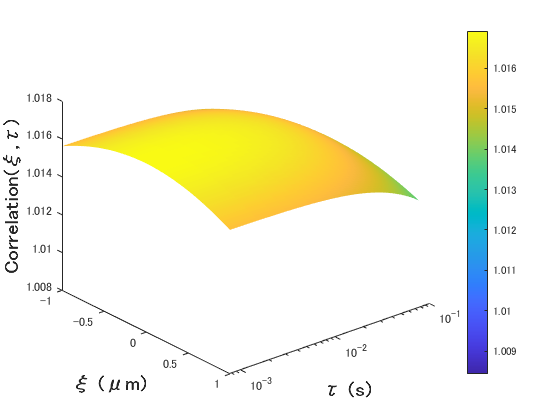

figure
s_afterFit = surface(KSAI,TAU, reshape(modelfun_3dim(parms, X), [size(COR,1), size(COR,2)]));
s_afterFit.EdgeColor = 'none';%これでメッシュ線なくなる
set(gca,'Yscale','log')
colorbar;
colormap;view(50,30);
xlabel('ξ (μm)','FontSize',14,'FontWeight','bold');
ylabel('τ (s)','FontSize',14,'FontWeight','bold');
zlabel('Correlation(ξ,τ)','FontSize',14,'FontWeight','bold');
xlim([-1 1]);